# Spatial filtering - 2

Created time : 2024/4/12 09:16

學號 : 109321019    姓名 : 涂价弘

## Exercise-6

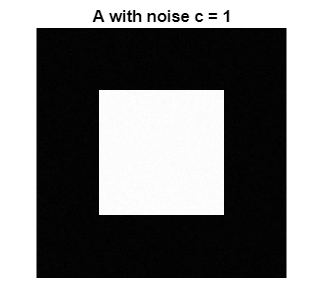

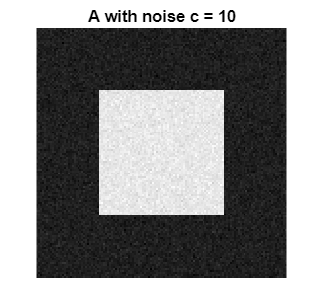

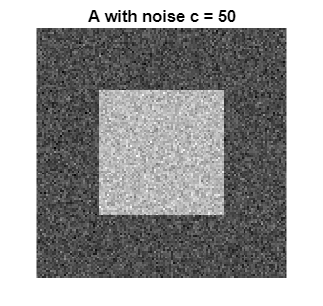

clf('reset')

A = zeros(128, 128);
A(33:96, 33:96) = 255 * ones(64, 64);

for c = [1 10 50]
    r = randn(size(A));
    I = A + c * r;
    figure, imshow(I, []);
    truesize([200, 200])
    title(['A with noise c = ', num2str(c)])
end

## Exercise-7

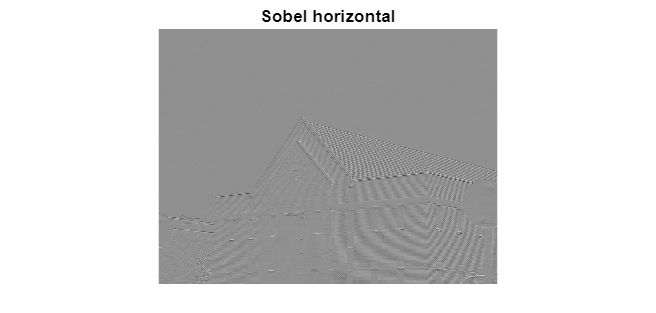

clf('reset')

f1 = ones(3, 3) / 9;
f2 = ones(5, 5) / 25;

I = imread('./images/house.jpg');
Sobel_x = [-1 -2 -1; 0 0 0; 1 2 1];

icx = filter2(Sobel_x, I);
figure, imshow(icx, [])
title('Sobel horizontal')
truesize([400 800])

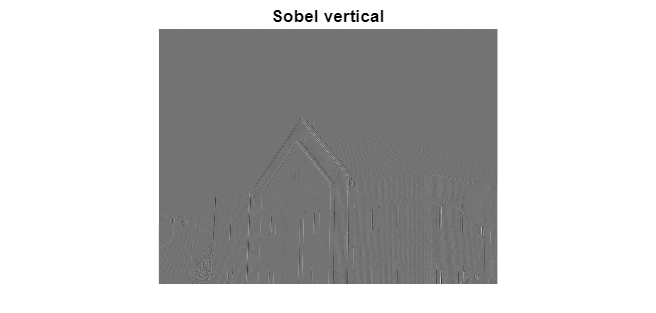


Sobel_y = Sobel_x';

icy = filter2(Sobel_y, I);
figure, imshow(icy, []);
title('Sobel vertical')
truesize([400 800])

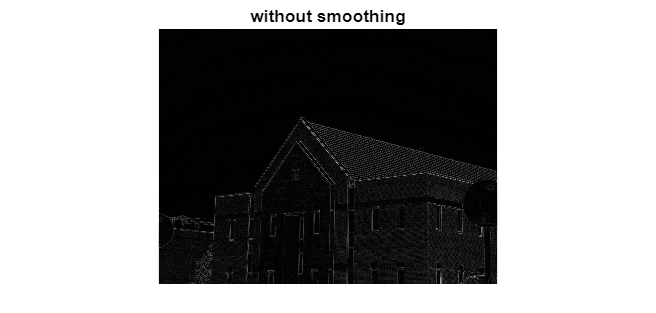


edge_p = abs(icx) + abs(icy);
figure, imshow(edge_p, []);
title('without smoothing')
truesize([400 800])

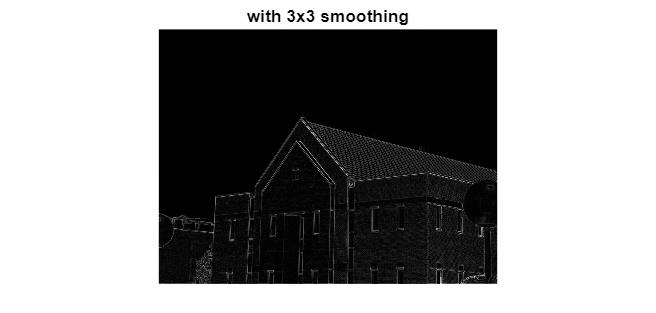


edge_p = abs(filter2(f1, icx)) + abs(filter2(f1, icy));
figure, imshow(edge_p, []);
title('with 3x3 smoothing')
truesize([400 800])

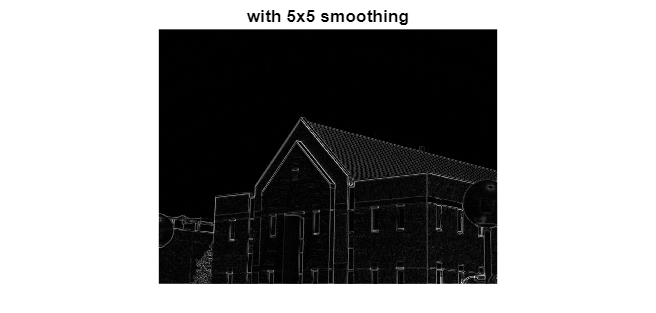


edge_p = abs(filter2(f2, icx)) + abs(filter2(f2, icy));
figure, imshow(edge_p, []);
title('with 5x5 smoothing')
truesize([400 800])

# Image Segmentation

## Exercise-1

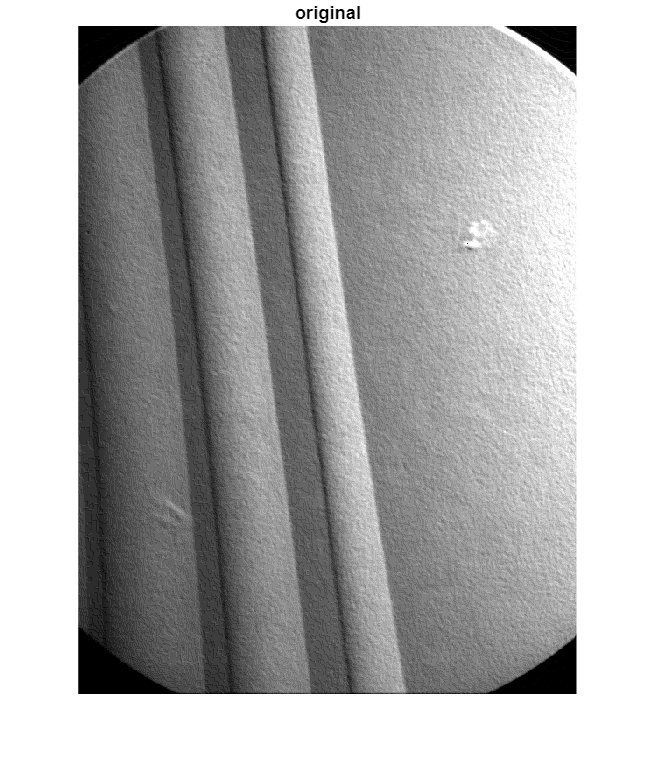

clf('reset')

I = imread('./images/turbine_blade_black_dot.tif');

figure, imshow(I, [])
title('original')

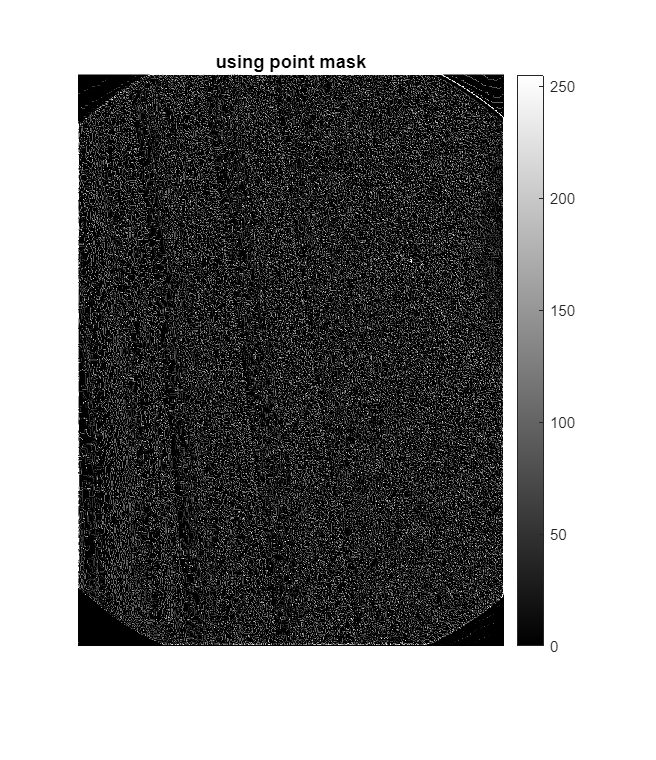


mask = [-1 -1 -1; -1 8 -1; -1 -1 -1];
R = filter2(mask, I);

figure, imshow(R, [0 255])
title('using point mask')
colorbar

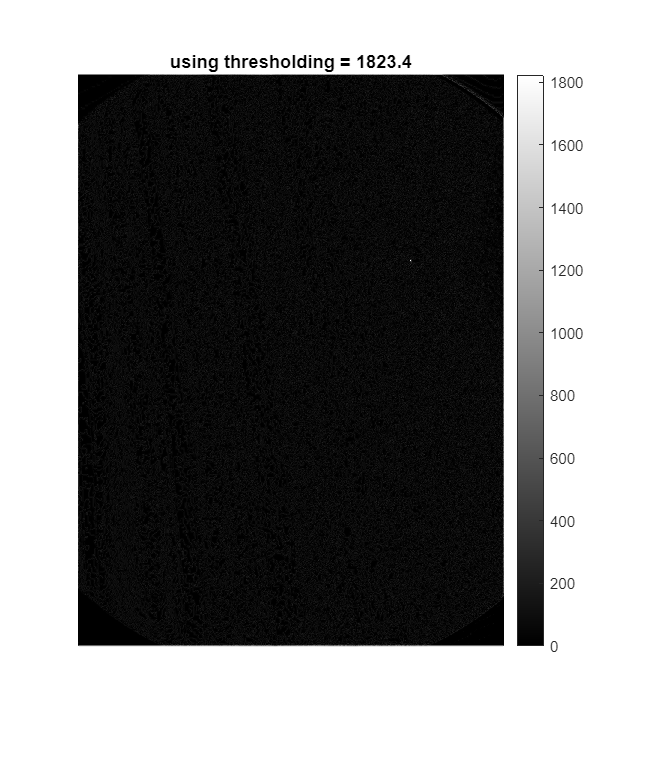


T = 0.9 * max(abs(R(:)));

figure, imshow(abs(R), [0 T])
title(['using thresholding = ', num2str(T)])
colorbar

## Exercise-3

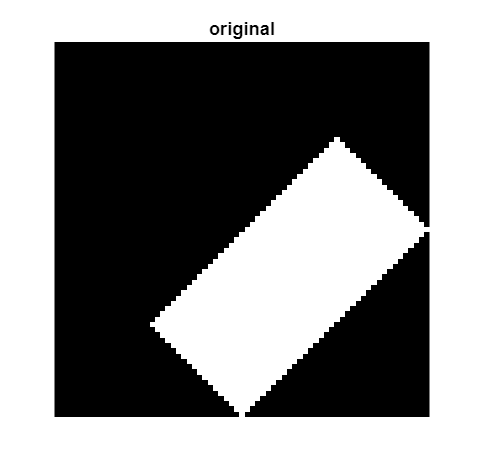

clf('reset')

I = [zeros(50, 25), 255 * ones(50,25)]';
I = imrotate(I, 45);

figure, imshow(I, [])
title('original')
truesize([300 300])

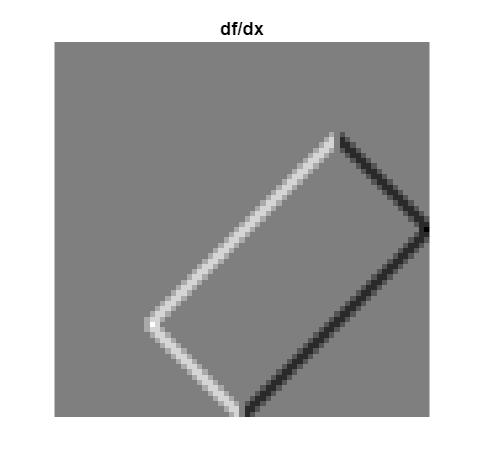


P = [-1 -1 -1; 0 0 0; 1 1 1];
P2 = P';

dy = filter2(P, I);
dx = filter2(P2, I);
angle = atan2(dy, dx);


figure, imshow(dx, [])
title('df/dx')
truesize([300 300])

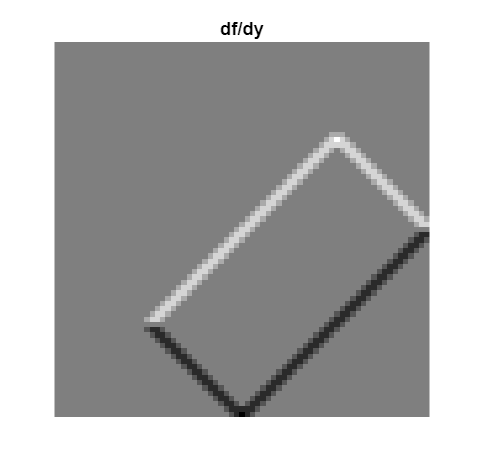


figure, imshow(dy, [])
title('df/dy')
truesize([300 300])

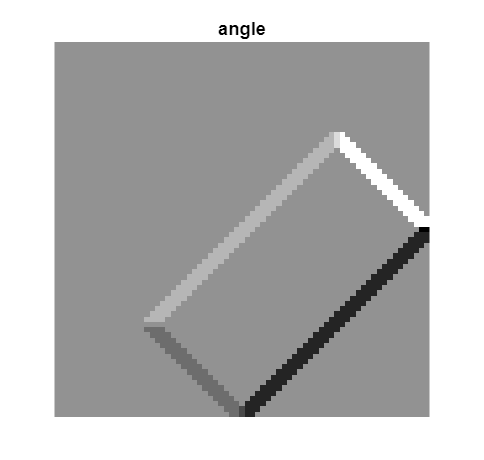


figure, imshow(angle, [])
title('angle')
truesize([300 300])

## Exercise-4

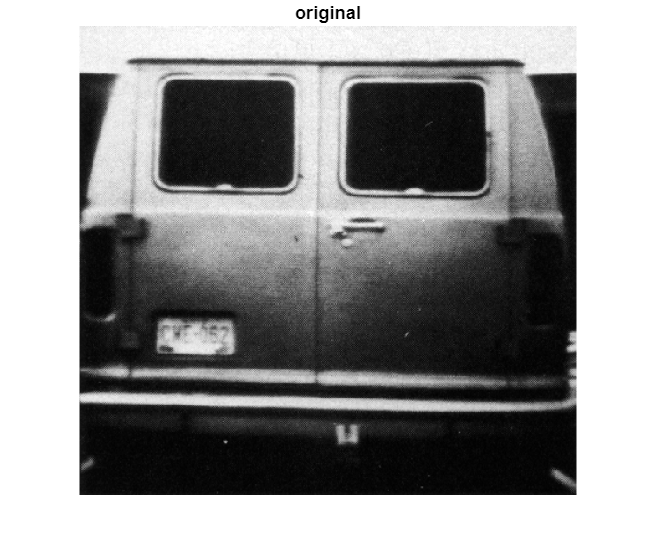

clf('reset')

I = imread('./images/van_original.tif');
P = [-1 -1 -1; 0 0 0; 1 1 1];
P2 = P';

dy = filter2(P, I);
dx = filter2(P2, I);
magnitude = abs(dy) + abs(dx);
angle = atan2(dy, dx);

figure, imshow(I, [])
title('original')

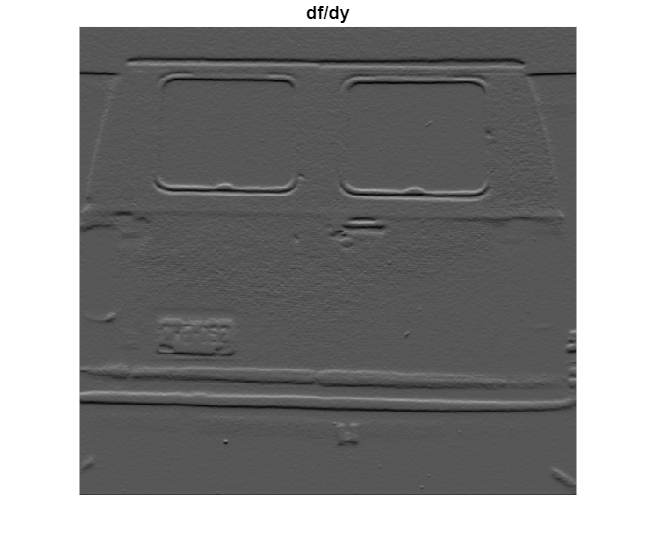


figure, imshow(dy, [])
title('df/dy')

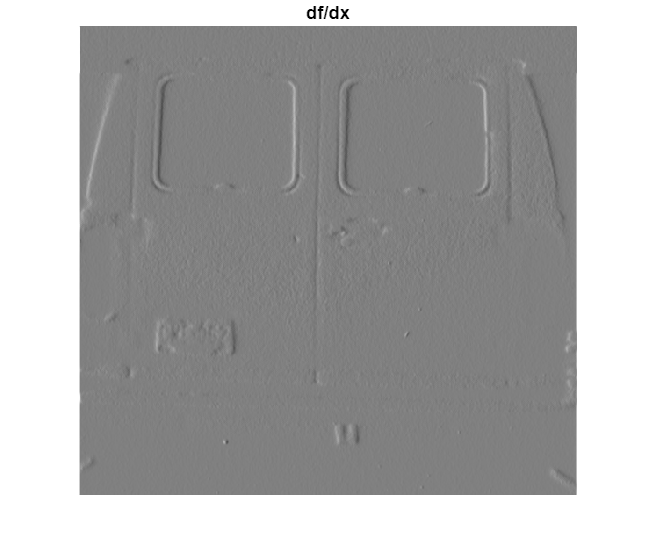


figure, imshow(dx, [])
title('df/dx')

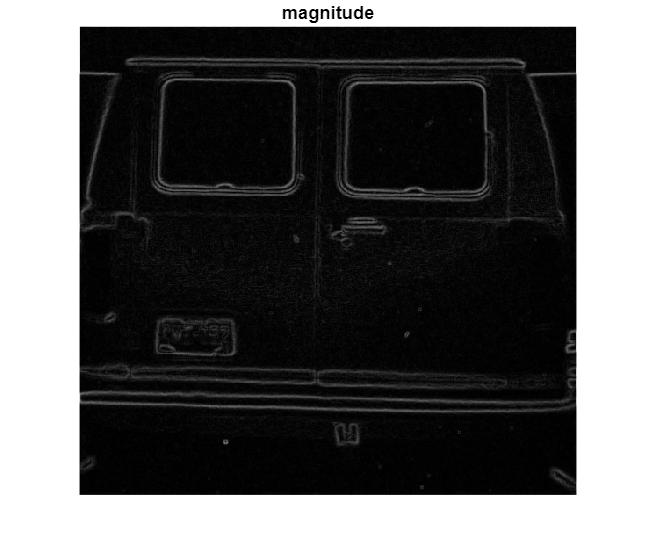


figure, imshow(magnitude, [])
title('magnitude')

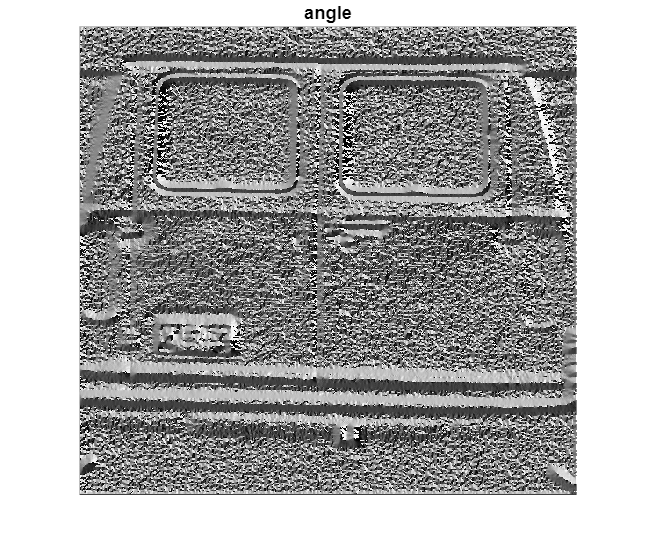


figure, imshow(angle, [])
title('angle')

## Exercise-5

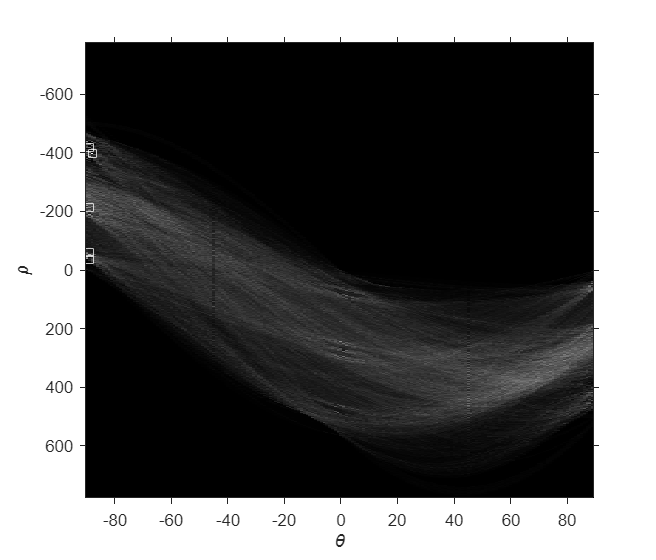

clf('reset')

I  = imread('./images/van_original.tif');
rotI = imrotate(I, 0,'crop');
BW = edge(rotI,'canny');
[H,T,R] = hough(BW);
imshow(H,[],'XData', T, 'YData', R, 'InitialMagnification', 'fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
P  = houghpeaks(H, 5, 'threshold', ceil(0.3 * max(H(:))));
x = T(P(:,2));
y = R(P(:,1));
plot(x, y, 's','color', 'white');

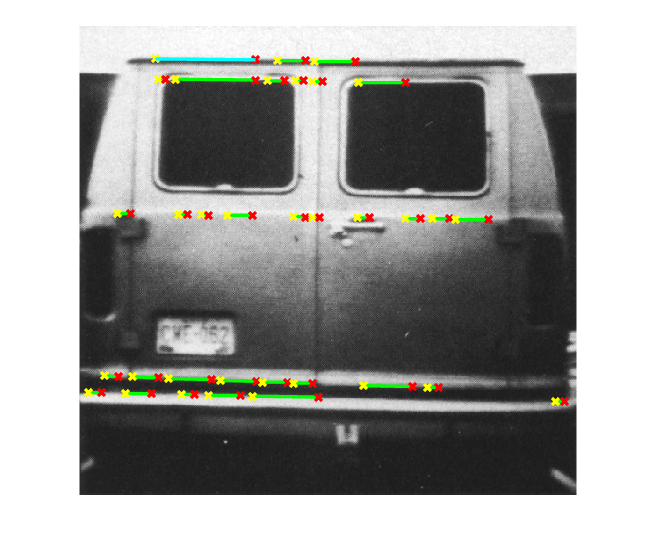


% Find lines and plot them
lines = houghlines(BW, T, R, P, 'FillGap', 5, 'MinLength', 7);
figure, imshow(rotI), hold on
max_len = 0;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:, 1), xy(:, 2), 'LineWidth', 2,'Color', 'green');
    % plot beginnings and ends of lines
    plot(xy(1, 1),xy(1, 2), 'x', 'LineWidth', 2,'Color', 'yellow');
    plot(xy(2, 1),xy(2, 2), 'x', 'LineWidth', 2,'Color', 'red');
    % determine the endpoints of the longest line segment
    len = norm(lines(k).point1 - lines(k).point2);
    if ( len > max_len)
        max_len = len;
        xy_long = xy;
    end
end
% highlight the longest line segment
plot(xy_long(:, 1), xy_long(:, 2), 'LineWidth', 2,'Color', 'cyan');